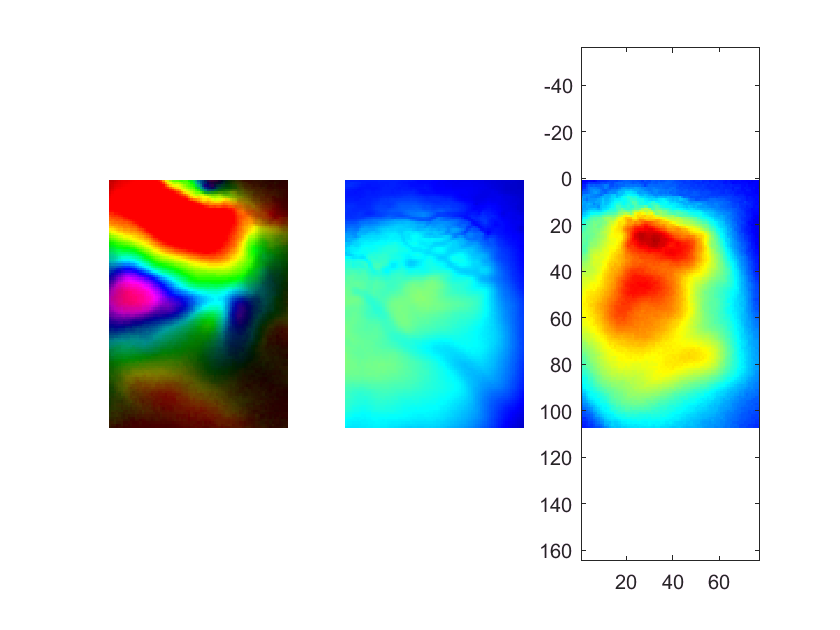

% Goal: pick points for analysis while comparing to visual area 
% boundaries & blood vessel location

figure

% POLAR MAP & AREA OVERLAY - needs do_topo

subplot(1,3,1);

topoPolarMap = polarMap(meanpolar{m},95);

% attempt to crop/downsize: 
downsize = 0.8; 
topoPolarMap = imresize(topoPolarMap,downsize);
topoPolarMap = topoPolarMap(yPtsCrop(1):yPtsCrop(2),xPtsCrop(1):xPtsCrop(2),:);

imshow(topoPolarMap)
    
hold on

% thinking out loud: 

% after I do the crop, the 1st y coordinate will be row 1 
% and the first x coordinate will become column 1 
% (new index/point value for that pixel)

% what is the center pixel of pre-cropped image (i.e. 0,0),
% what is the center pixel of the the cropped area? 
% The change in x & y for the center point should
% be the same for all points because there's no stretching... 

% pre-crop dimensions: 520 x 640
% center = row 260, column 320

% rough crop dimensions: 100 x 75
% center = row 50, column 37

% displacement due to crop -> y = 260-50 = 210, x = 320-37 = 283

% remember x pts are really y pts and vice versa... 
testXpts = xpts+283; 
testYpts = ypts-210; % PROBLEM: gives negative values

% plot(ypts,xpts,'w.','Markersize',2)
plot(testYpts,testXpts,'w.','Markersize',2)

axis equal

% TIF pic

tifPic = imread('081921_G6H305RT_RIG2_THRESH_37711.tif');

downsize = 0.4; 

tifPic = imresize(tifPic,downsize);

tifPic = tifPic(yPtsCrop(1):yPtsCrop(2),xPtsCrop(1):xPtsCrop(2),:);

subplot(1,3,2);
imshow(tifPic) % Q; how to keep black & white?

axis equal

% ACTIVATION IMAGE - *needs onsetDf*

% image of highest contrast & duration during peak response
clear c7d5trials
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,idxOnsetsMeetsCriteria);
c7d5trials = conAndDurOrderedByTrialMeetCriteria(1,:) == max(uniqueContrasts) & conAndDurOrderedByTrialMeetCriteria(2,:) == max(uniqueDurations);
% always pick the 4th, 5th, 6th, & 7th frames following stim onset, b/c that shows
% "imprint" of vis ctx best and captures how higher value stims give not only
% greater peaks but also longer activation
clear actImIdx
% actImIdx = [stimOnsetFrame+4,stimOnsetFrame+5,stimOnsetFrame+6,stimOnsetFrame+7]; % stimOnsetFrame defined in making onsetDf code
actImIdx = peakFrameIdx;
% get all act im frames at highest c & d
clear allActImFrames
allActImFrames = onsetDf(:,:,actImIdx,c7d5trials); 
% take the average of the image across frames
clear meanActImFrames
meanActImFrames = squeeze(mean(allActImFrames,3));
meanActImFrames = mean(meanActImFrames,3);

subplot(1,3,3);

range = [0 0.038]; 

imagesc(meanActImFrames,range)
%imshow(meanActImFrames,range)

colormap('jet');

hold on

plot(testYpts,testXpts,'w.','Markersize',2)
% plot(ypts,xpts,'w.','Markersize',2)

axis equal

% pick 5 pts - V1, motor ctx, 3 HVAs

clear xPickedPts 
clear yPickedPts 
    
for i = 1:5
   
    hold on
    [xPickedPts(i) yPickedPts(i)] = ginput(1);
    plot(xPickedPts(i),yPickedPts(i),'*');
   
end